panel = irdata_151825(1, 2).ImpulseResponse

panel = struct with fields:
         Time: [176400×1 double]
    Amplitude: [176400×1 double]


source = irdata_151825(2, 2).ImpulseResponse

source = struct with fields:
         Time: [176400×1 double]
    Amplitude: [176400×1 double]


Unable to resolve the name 'panel.Time'.

panel.Time = panel.Time(1:44100)
panel.Amplitude = panel.Amplitude(1:44100)
source.Time = source.Time(1:44100)
source.Amplitude = source.Amplitude(1:44100)

panel.Amplitude = panel.Amplitude / max(abs(panel.Amplitude))
source.Amplitude = source.Amplitude / max(abs(source.Amplitude))

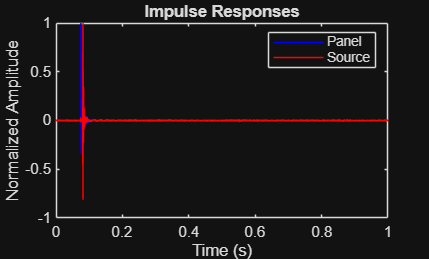

figure;
plot(panel.Time, panel.Amplitude, 'b', source.Time, source.Amplitude, 'r');
legend('Panel', 'Source');
xlabel('Time (s)');
ylabel('Normalized Amplitude');
title('Impulse Responses');

lamda = 5e-2;
H = fft(panel.Amplitude);

H_conj = conj(H);

G = H_conj ./ (H .* H_conj + lamda);

panel.Inverse = ifft(G)

panel = struct with fields:
         Time: [44100×1 double]
    Amplitude: [44100×1 double]
      Inverse: [44100×1 double]


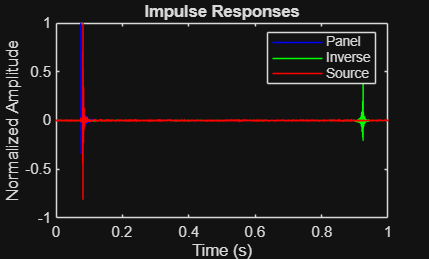

figure;
plot(panel.Time, panel.Amplitude, 'b', panel.Time, panel.Inverse, 'g', source.Time, source.Amplitude, 'r');
legend('Panel', 'Inverse', 'Source');
xlabel('Time (s)');
ylabel('Normalized Amplitude');
title('Impulse Responses');

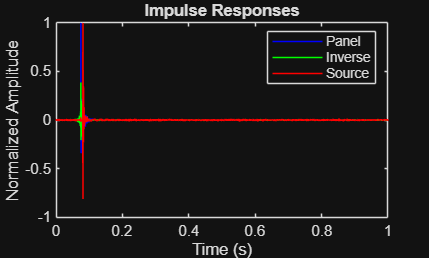

panel.Inverse = fliplr(panel.Inverse);

figure;
plot(panel.Time, panel.Amplitude, 'b', panel.Time, panel.Inverse, 'g', source.Time, source.Amplitude, 'r');
legend('Panel', 'Inverse', 'Source');
xlabel('Time (s)');
ylabel('Normalized Amplitude');
title('Impulse Responses');